Сравнительное исследование схемы работы с автокодировщиком и без него

# Содержание исседования

Выполнено сравнение различных методов формирования пространств признаков с плохо различимыми сигналами. Исследованы различные преобразования: 

- ПКЛ, 

- ВП, 

- КВП, 

- АКВП, 

- ПФ, 

- АПФ. 

Исследованы три способа построения системы распознавания: 

- преобразование-классификатор,

- автокодировщик-классификатор (рассмотрено в рамках последней схемы с отсутствием преобразования),

- преобразование-автокодировщик-классификатор.

# Формирование данных

Возможно выбрать наборы тестовых сигналов:

- последвательность из синуса и гауссовского импульса и обратная последовательность,

- конус и сфера.

## Выбор набора данных

dataset = "Синус и гаусс"

dataset = "Синус и гаусс"

n_dim = 32

n_dim = 32

n_fvs =128

n_fvs = 128

n_fvs_tst =128

n_fvs_tst = 128

sigma_trn = 0.05

sigma_trn = 0.0500

sigma_tst = 0.08

sigma_tst = 0.0800

t_types = {'afft','fft','acwt','cwt','wt','pca'}; n_types = length(t_types);
if isequal(dataset, "Синус и гаусс")
    [rps_src, rps_shft] = create_test_signal('n_real', n_fvs, 'length', n_dim, 'sigma', sigma_trn);
    meta = repmat([0;1],n_fvs,1); % Ответы
    meta.'
    [tst_rps, tst_rps_shft] = create_test_signal('n_real', n_fvs_tst, 'length', n_dim, 'sigma', sigma_tst);
    tst_meta = repmat([0;1],n_fvs_tst,1); % тестовые ДП
    tst_meta.'
else
    warning('get rps')
end

	Отн. С/Ш: 

	Отн. С/Ш: 

	Окно случ сдвига: 2 длин исх


ans =      0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1


	Отн. С/Ш: 

	Отн. С/Ш: 

	Окно случ сдвига: 2 длин исх


ans =      0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1


result_crossentropy = table(zeros(n_types,1), zeros(n_types,1), zeros(n_types,1),'RowNames',t_types, 'VariableNames', {'clf','ae_clf','coder_clf'});
result_accuracy = table(zeros(n_types,1), zeros(n_types,1), zeros(n_types,1),'RowNames',t_types, 'VariableNames', {'clf','ae_clf','coder_clf'});

Осциллограммы ДП

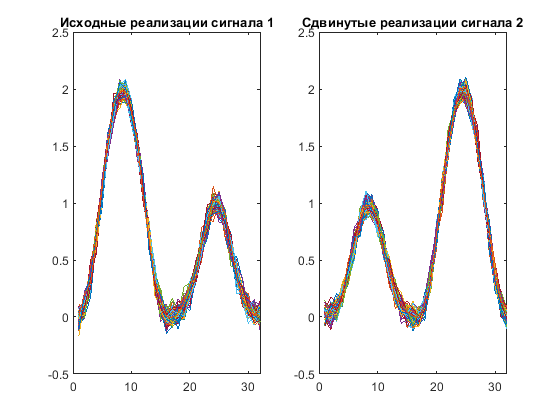

figure();
subplot(121); plot(rps_src(1:2:end,:).') % Тестовые не сдвинутые сигналы
title('Исходные реализации сигнала 1');
subplot(122); plot(rps_src(2:2:end,:).') % Тестовые не сдвинутые сигналы
title('Сдвинутые реализации сигнала 2');

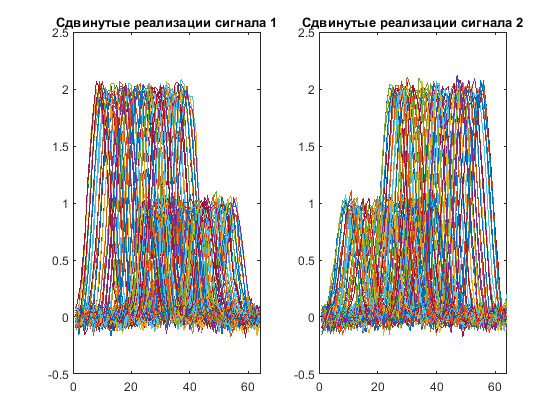

figure();
subplot(121); plot(rps_shft(1:2:end,:).') % Тестовые сдвинутые сигналы
title('Сдвинутые реализации сигнала 1');
subplot(122); plot(rps_shft(2:2:end,:).') % Тестовые сдвинутые сигналы
title('Сдвинутые реализации сигнала 2');

## Выбор параметров преобразования

transform ='acwt' 

transform = 'acwt'

system_model = SystemModel;
if strcmp(transform, 'wt'), rpfun =  @(x) system_model.transform(x, transform, 'sym3'); % выбор преобразования
elseif strcmp(transform, 'wt'), rpfun =  @(x) system_model.transform(x, transform, 'dtf3'); % выбор преобразования
else, rpfun =  @(x) system_model.transform(x, transform); % выбор преобразования
end
result_accuracy

result_accuracy = 6×3 table
              clf      ae_clf     coder_clf
            _______    _______    _________

    afft    0.50781        0.5     0.51563 
    fft     0.75391    0.71484     0.67578 
    acwt    0.90234    0.79297     0.84766 
    cwt           0          0           0 
    wt       0.8125    0.92188      0.9375 
    pca         0.5    0.58594           0 


# Схема "преобразование-классификатор"

### Обучение модели

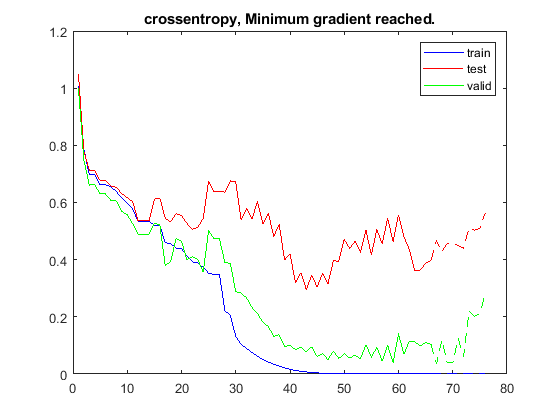

%% 1/ обучение клф без АК
x = rpfun(rps_shft).';  % формирование вектора признаков
y = meta.';             % целевой вектор

cfnet = patternnet([8 4]);     % обучение классификатора
cfnet = configure(cfnet,x, y);      % нструктуры сети
cfnet.trainParam.max_fail = 10;     % число ошибок на валидационной выборке
cfnet.trainParam.showWindow = false;
[cfnet, tr_chars] = train(cfnet,x,y,'useGPU','no');    % обучение классификатора

plot_performance(tr_chars);

### Матрица ошибок для обучающей выборки

x = rpfun(rps_shft).';  % формирование вектора признаков
y = meta.';             % целевой вектор

pred = cfnet(x);
figure(); 
subplot(221); confusionchart(confusionmat((y>0.5),(pred>0.5)),{'Объект 1', 'Объект 2'}); title('Ошибки на обучающей выборке')

### Матрицы ошибок для тестовой выборки

x = rpfun(tst_rps_shft).';
y = tst_meta.';
pred = cfnet(x);
conf_mx = confusionmat((y>0.5),(pred>0.5));
result_crossentropy{transform,'clf'} = perform(cfnet,y,pred);
result_accuracy{transform,'clf'} = sum(conf_mx(eye(length(conf_mx))==1),'all')/sum(conf_mx,'all');

disp({'Средняя абсолютная ошибка',mean(abs(pred-y))})

    'Средняя абсолютная ошибка'    [0.1926]



disp({'Перекрестная энтропия',perform(cfnet,y,pred)})

    'Перекрестная энтропия'    [1.6397]



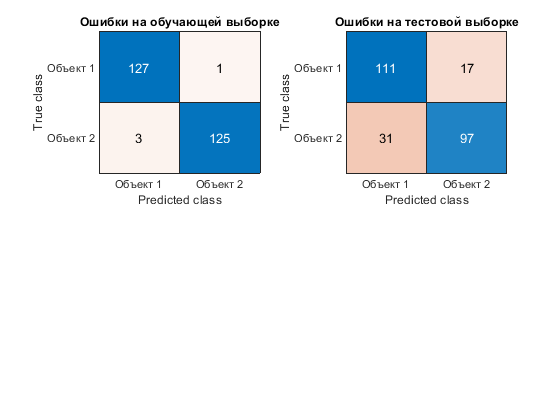

subplot(222); confusionchart(conf_mx,{'Объект 1', 'Объект 2'}); title('Ошибки на тестовой выборке')

# Схема "преобразование-автокодировщик-классификатор"

## Обучение автокодировщика

%% 1/ обучение клф без АК
x_ac_in = rpfun(rps_shft).';  % формирование вектора признаков
x_ac_out = rpfun(rps_src).';

ac_config = [8, 4];
acnet = feedforwardnet(ac_config); acnet = configure(acnet,x_ac_in, x_ac_out);
acnet.layers{end}.transferFcn = 'tansig';   acnet.trainParam.max_fail = 10; acnet.trainParam.showWindow = false;
[acnet, tr_chars]  = train(acnet,x_ac_in,x_ac_out,'useGPU','yes');

NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


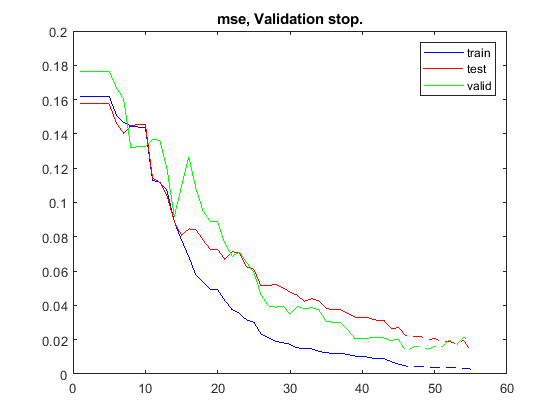

plot_performance(tr_chars);

## Обучение классификатора

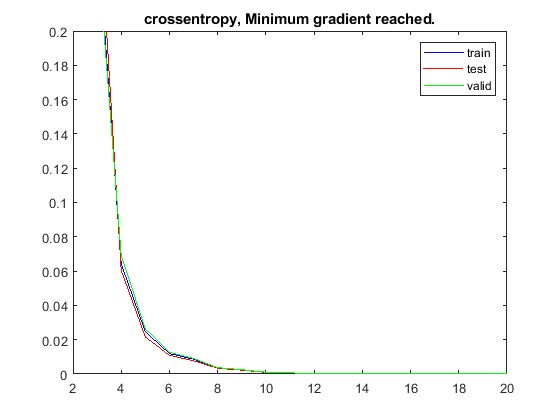

x_ac_out = rpfun(rps_src).';
y = meta.';             % целевой вектор

cf_config = 2;
cfnet = patternnet(cf_config);     % обучение классификатора
cfnet = configure(cfnet,x_ac_out, y);      % настройка структуры сети
cfnet.trainParam.max_fail = 10;     % число ошибок на валидационной выборке
cfnet.trainParam.showWindow = false;
[cfnet, tr_chars] = train(cfnet,x_ac_out,y,'useGPU','yes');    % обучение классификатора
plot_performance(tr_chars);

### Матрица ошибок для обучающей выборки

x = rpfun(rps_shft).';
y = meta.';             % целевой вектор

pred = cfnet(acnet(x_ac_in));     % последовательность из АК и классификатора

subplot(223); confusionchart(confusionmat((y>0.5),(pred>0.5)),{'Объект 1', 'Объект 2'});
title('Ошибки на обучающей выборке')

### Матрицы ошибок для тестовой выборки

x = rpfun(tst_rps_shft).';
y = tst_meta.';
pred = cfnet(acnet(x));
conf_mx = confusionmat((y>0.5),(pred>0.5));
result_crossentropy{transform,'ae_clf'} = perform(cfnet,y,pred);
result_accuracy{transform,'ae_clf'} = sum(conf_mx(eye(length(conf_mx))==1),'all')/sum(conf_mx,'all');

disp({'Средняя абсолютная ошибка',mean(abs(pred-y))})

    'Средняя абсолютная ошибка'    [0.2116]



disp({'Перекрестная энтропия',perform(cfnet,y,pred)})

    'Перекрестная энтропия'    [2.4735]



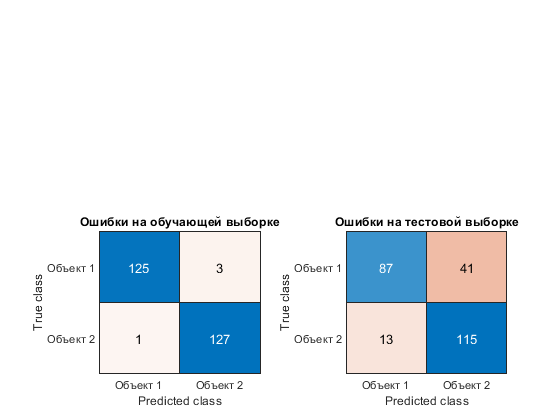

subplot(224);  confusionchart(conf_mx,{'Объект 1', 'Объект 2'});
title('Ошибки на тестовой выборке')

# Схема "преобразование-кодировщик-классификатор"

## Обучение автокодировщика

%% 1/ обучение клф без АК
x_ac_in = rpfun(rps_shft).';  % формирование вектора признаков
x_ac_out = rpfun(rps_src).';

ac_config = [8, 4];
acnet = feedforwardnet(ac_config); acnet = configure(acnet,x_ac_in, x_ac_out);
acnet.layers{end}.transferFcn = 'tansig';   acnet.trainParam.max_fail = 10; acnet.trainParam.showWindow = false;
[acnet, tr_chars]  = train(acnet,x_ac_in,x_ac_out,'useGPU','yes');

NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


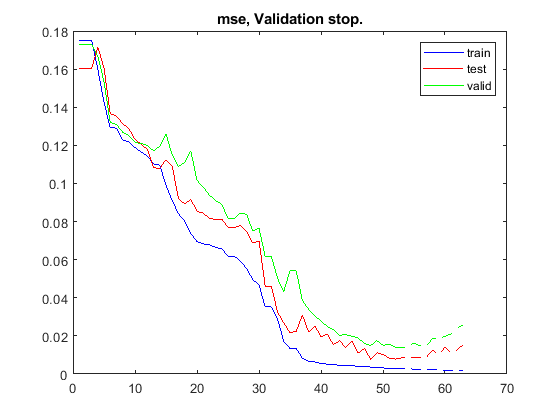

plot_performance(tr_chars);

## Обучение классификатора на выходах кодировщика

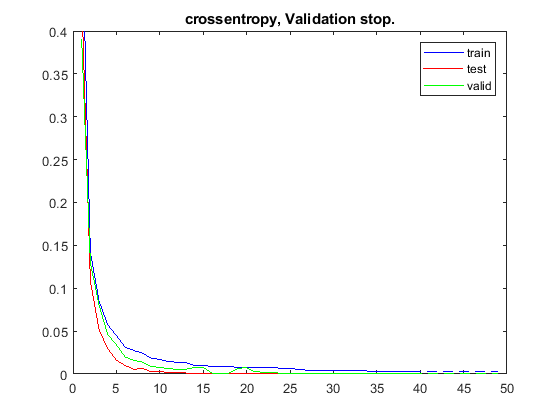

% формирование кодера
[~, encoder_split] = min(ac_config);
encoder_config = ac_config(1:encoder_split);
codenet = feedforwardnet(encoder_config(1:end-1));
codenet = configure(codenet,x_ac_in,randn(encoder_config(end),size(x_ac_in,2)));
codenet.layers{end}.transferFcn = 'tansig';   codenet.trainParam.max_fail = 10;
codenet.IW(:) = acnet.IW(1:encoder_split);
for from_l = 1:encoder_split
    for to_l = 1:(encoder_split)
        codenet.LW(to_l, from_l) = acnet.LW(to_l, from_l);
    end
end
codenet.b(:) = acnet.b(1:encoder_split);

x = codenet(rpfun(rps_shft).');
y = meta.';             % целевой вектор

cf_config = [];
cfnet = patternnet(cf_config);     % обучение классификатора
cfnet = configure(cfnet,x, y);      % настройка структуры сети
cfnet.trainParam.max_fail = 10;     % число ошибок на валидационной выборке
cfnet.trainParam.showWindow = false;
[cfnet, tr_chars] = train(cfnet,x,y,'useGPU','yes');    % обучение классификатора
plot_performance(tr_chars);

### Матрица ошибок для обучающей выборки

x = rpfun(rps_shft).';
y = meta.';             % целевой вектор

%% доработатать соединение усеченного автокодировщика и классификатора
pred = cfnet(codenet(x));     % последовательность из АК и классификатора

subplot(223); confusionchart(confusionmat((y>0.5),(pred>0.5)),{'Объект 1', 'Объект 2'});
title('Ошибки на обучающей выборке')

### Матрицы ошибок для тестовой выборки

x = rpfun(tst_rps_shft).';
y = tst_meta.';
pred = cfnet(codenet(x));
conf_mx = confusionmat((y>0.5),(pred>0.5));
result_crossentropy{transform,'coder_clf'} = perform(cfnet,y,pred);
result_accuracy{transform,'coder_clf'} = sum(conf_mx(eye(length(conf_mx))==1),'all')/sum(conf_mx,'all');

disp({'Средняя абсолютная ошибка',mean(abs(pred-y))})

    'Средняя абсолютная ошибка'    [0.2200]



disp({'Перекрестная энтропия',perform(cfnet,y,pred)})

    'Перекрестная энтропия'    [5.5429]



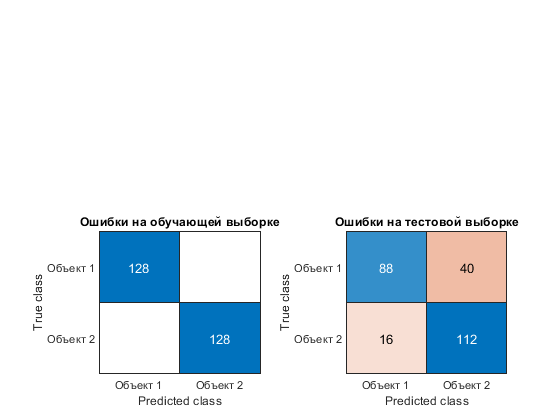

subplot(224);  confusionchart(conf_mx,{'Объект 1', 'Объект 2'});
title('Ошибки на тестовой выборке')

# Приложение 1. Служебные функции

## Примеры тестовых сигналов

% [rps_src, rps_shft] = create_test_signal('n_real', 4, 'length', 16, 'sigma', 0.1);
% figure();
% subplot(211); plot(rps_src(1:2:end,:).') % Тестовые не сдвинутые сигналы
% title('Исходные реализации сигнала 1');
% subplot(212); plot(rps_src(2:2:end,:).') % Тестовые не сдвинутые сигналы
% title('Сдвинутые реализации сигнала 2');
% figure();
% subplot(211); plot(rps_shft(1:2:end,:).') % Тестовые сдвинутые сигналы
% title('Сдвинутые реализации сигнала 1');
% subplot(212); plot(rps_shft(2:2:end,:).') % Тестовые сдвинутые сигналы
% title('Сдвинутые реализации сигнала 2');
% clear rps_shft rps_src

## Функции

function [rps_src, rps_shifted] = create_test_signal(varargin)
    signal_length = get_value(varargin, 'length', 32);
    sigma_noise = get_value(varargin, 'sigma', 0);
    n_realizations = get_value(varargin, 'n_real', 16);
    
    x_axis = linspace(-0.99*pi, 0.99*pi, ceil(signal_length/2));        % ось времени
    signal_cos = cos(x_axis)+1;                                         % фрагмент из косинуса
    signal_gauss = gaussmf(x_axis,[pi/3, 0]);                           % фрагмент из гаусса
    rps = [signal_cos, signal_gauss; signal_gauss, signal_cos];         % формирование базового сигнала 
    if size(rps,2)>signal_length, rps(:, signal_length+1:end)=[]; end   % удалить возникшие лишние отсчёты
    rps_src = RPTools.add_noise(rps, [], sigma_noise, n_realizations, 1);   % не смещенные реализации
    rps_shifted = RPTools.add_noise(rps, [], sigma_noise, n_realizations, 2);   % смещенные реализации
end

function h = plot_performance(chars)
    h = figure(); 
    x = 1:chars.best_epoch;
    plot(x, chars.perf(x), 'b', x, chars.tperf(x), 'r', x, chars.vperf(x), 'g'); hold on
    x = chars.best_epoch:chars.num_epochs;
    plot(x, chars.perf(x), '--b', x, chars.tperf(x), '--r', x, chars.vperf(x), '--g');
    ylim([0 0.2])
    title([chars.performFcn,', ',chars.stop])
    legend('train','test','valid');

end

% поиск значения именнованного параметра по его имени
function parameter_value = get_value(arg_in, parameter_name, varargin)
%get_value Функция выполняет поиск имени параметра и выводит его значение
%   Аргументы:
%   arg_in - массив ячеек с последовательно идущими именами и значениями параметров - можно вводить varargin
%   parameter_name - строковое значение имени параметра, значение которого требуется найти
%   varargin - третьим элементом может быть задано значение параметра по умолчанию.
%   KeywordArguments(varargin, 'Parameter_to_find', 69) % 69 будет присвоено, если параметра нет в varargin
    i = find(strcmp(parameter_name,arg_in),1);
    if isempty(i)
        if nargin == 3
            parameter_value = varargin{1};
        else 
            error(['Параметр ' parameter_name ' не найден в вводе'])
        end
    elseif length(i)==1
        parameter_value = arg_in{i+1};    %
    else
        error(['Имя параметра ' parameter_name ' найдено несколько раз.'])
    end
end